# ***LCS HW3 Software Assignment***

## ***Dr.Ahi Behzad***

#### ***MohammadParsa Dini 400101204***

***Part 6:***

***6.1***

We are given a transfer function $H(s) = \frac{1-s}{(s+1)(2s+1)}$ , we wish to show its frequency response first:

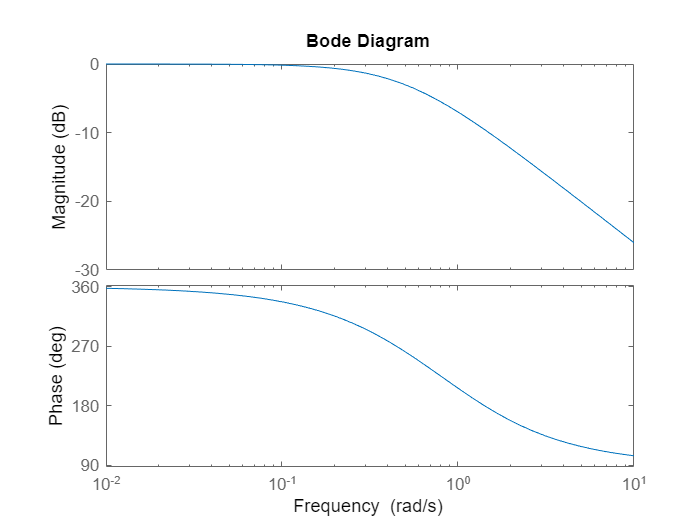

clear;
clc;
figure();
s = tf('s');
G = (1-s)/((s+1)*(2*s+1));
bode(G);

As we can see $G(s)$ is a low pass filter.

Now we want to generate the impulse signal to find the impulse response of the system.

we will define an approximation of Dirac delta function: $f_\epsilon = \mathbb{1} ( -\frac{\epsilon}{2} \leq t \leq \frac{\epsilon}{2})$ and we will approximate it as below:

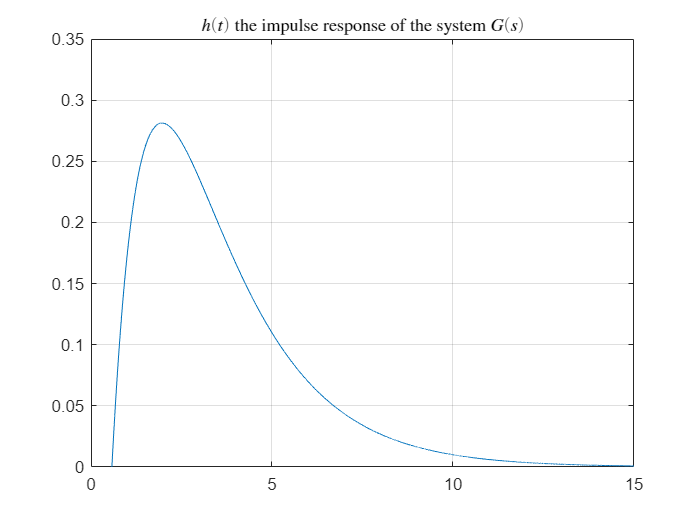

% defining the time sample 
dt = 0.001;
epsilon = dt;
t = 0:dt:15;
% defining the input 
delta_dirac = zeros(size(t));
delta_dirac(1) = 1/(3*epsilon);
delta_dirac(2) = 1/(3*epsilon);
delta_dirac(3) = 1/(3*epsilon);
% plotting
h_impulse = lsim(G,delta_dirac,t);
figure();
plot(t,h_impulse);
grid on;
title('$h(t)$ the impulse response of the system $G(s)$',Interpreter='latex');
xlim([0,15]);
ylim([0 0.35]);

***6.2***

now we will get the impulse resonse using the*** ilaplace() ***of matlab we will get the inverse Laplace tranform of the transfer function which  infact is its time domain impulse response and we will see that the results match!

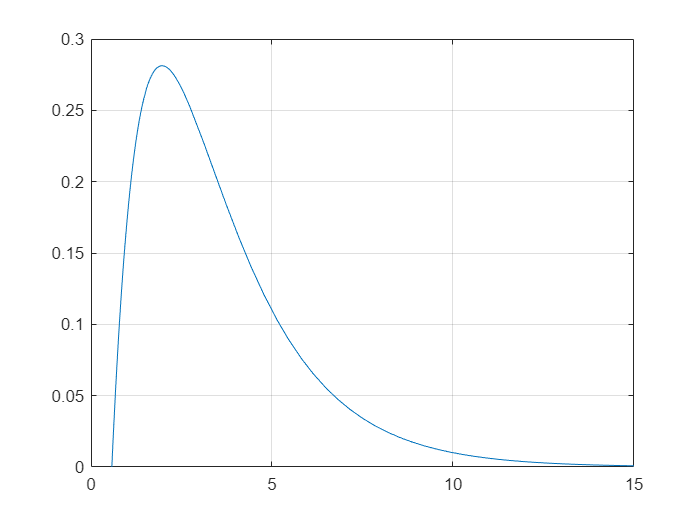

clear;
syms s;
figure();
dt = 0.001;
G = (1-s)/((s+1)*(2*s+1));
fplot(ilaplace(G),[0 15]);
ylim([0 0.3]);
grid on;

***6.3***

Here we will get the space model representation of the system

num = [-1 1];
den = [2 3 1];
syms t;
[A, B, C, D] = tf2ss(num, den)

A =    -1.5000   -0.5000
    1.0000         0


B =      1
     0


C =    -0.5000    0.5000


D = 0

So using these equations we will reach the space model representation of $G(s)$


$$\begin{array}{l}
\dot{x} =A\;x+B\;u\\
y=C\;x+D\;u
\end{array}$$


We can also use $G(s) = C (sI-A)^{-1} B + D$ to plot the impulse response:

figure();
h_ss = ss(tf(num, den));
fplot(h_ss.C * expm((h_ss.A) * t) * h_ss.B + h_ss.D, [0 15] );
ylim([0 0.3]);
grid on;

***6.4***

This is the result of getting the impulse response with ***impulse() ***function. 

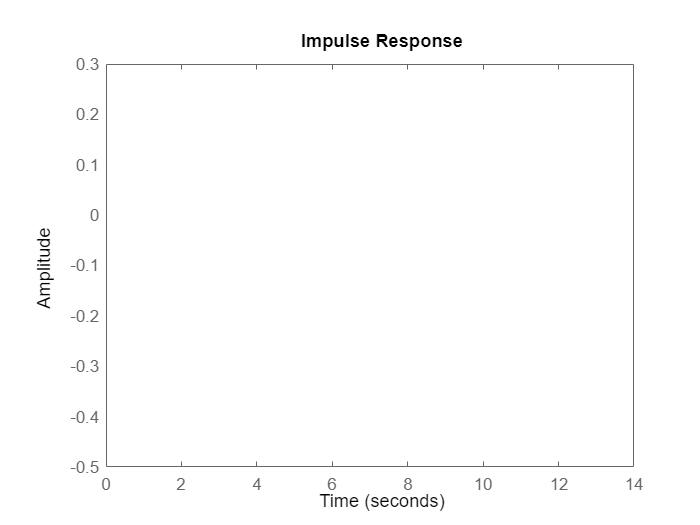

clear;
figure();
s = tf('s');
G = (1-s)/((s+1)*(2*s+1));
impulse(G);

***6.5***

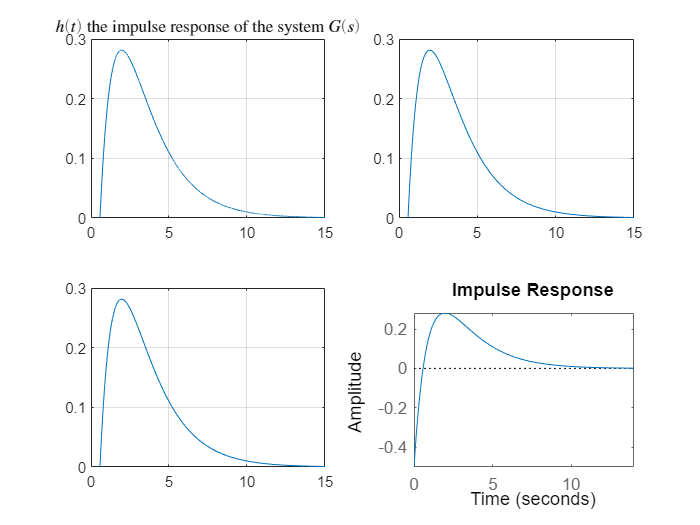

figure();
subplot(2,2,1);
s = tf('s');
G = (1-s)/((s+1)*(2*s+1));
dt = 0.001;
epsilon = dt;
t = 0:dt:15;
delta_dirac = zeros(size(t));
delta_dirac(1) = 1/(3*epsilon);
delta_dirac(2) = 1/(3*epsilon);
delta_dirac(3) = 1/(3*epsilon);
h_impulse = lsim(G,delta_dirac,t);
plot(t,h_impulse);
grid on;
title('$h(t)$ the impulse response of the system $G(s)$',Interpreter='latex');
xlim([0,15]);
ylim([0 0.3]);

subplot(2,2,2);
syms s;
dt = 0.001;
G = (1-s)/((s+1)*(2*s+1));
fplot(ilaplace(G),[0 15]);
ylim([0 0.3]);
grid on;

subplot(2,2,3);
syms t;
num = [-1 1];
den = [2 3 1];
h_ss = ss(tf(num, den));
fplot(h_ss.C * expm((h_ss.A) * t) * h_ss.B + h_ss.D, [0 15] );
ylim([0 0.3]);
grid on;

subplot(2,2,4);
s = tf('s');
G = (1-s)/((s+1)*(2*s+1));
impulse(G);

It's crystal clear that all these plots are showing the impulse response of $G(s)$

As expected, $e^{At}$ matrices calculated from those ways are identical!

clear;
num = [-1 1];
den = [2 3 1];
syms s t;
h_ss = ss(tf(num, den));
G = inv((s*eye(2,2) - h_ss.A));
exp_At = ilaplace(G);
exp_At_ = expm(h_ss.A * t);
exp_At

$$exp\_At = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}}\\ 2\,{\mathrm{e}}^{-\frac{t}{2}}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-\frac{t}{2}}-{\mathrm{e}}^{-t} \end{array}\right)$$

exp_At_

$$exp\_At\_ = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-\frac{t}{2}}\\ 2\,{\mathrm{e}}^{-\frac{t}{2}}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-\frac{t}{2}}-{\mathrm{e}}^{-t} \end{array}\right)$$

G

$$G = \left(\begin{array}{cc} \frac{2\,s}{2\,s^{2}+3\,s+1} & -\frac{1}{2\,s^{2}+3\,s+1}\\ \frac{2}{2\,s^{2}+3\,s+1} & \frac{2\,s+3}{2\,s^{2}+3\,s+1} \end{array}\right)$$